%% CSVファイルの読み込み
filename = 'Uniform - with Artillery/IrpinModel Vary Site-Selection Artillery Active-table.csv';
data = readtable(filename);

disp(data);

    x_runNumber_    turn_on_artillery_    turn_on_stop_conditions_      site_selection_mode      x_step_    battle_outcome    total_infantry_crossed    total_infantry_casualties_10    total_infantry_used    ticks
    ____________    __________________    ________________________    _______________________    _______    ______________    ______________________    ____________________________    ___________________    _____

          1              {'true'}                 {'true'}            {'01 Shortest Bridges'}     9780       {'Retreat'}                  0                         4510                       5540            9780 
          6         

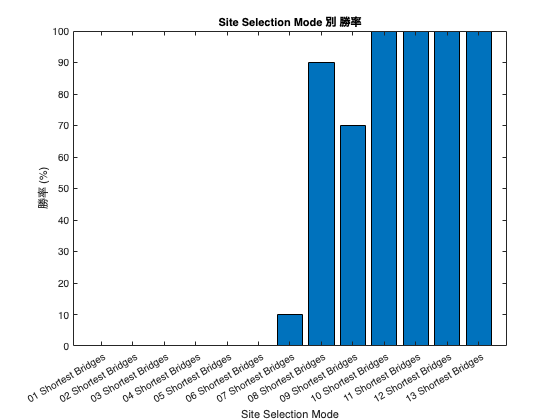


%% サイト選択モードの抽出と勝率計算
siteModes = unique(data.site_selection_mode);
winRatio = zeros(length(siteModes),1);
for i = 1:length(siteModes)
    idx = strcmp(data.site_selection_mode, siteModes{i});
    winRatio(i) = sum(strcmp(data.battle_outcome(idx), 'Victory')) / sum(idx) * 100;
end

%% Graph 1: Site Selection Mode 別 勝率の棒グラフ
figure;
bar(categorical(siteModes), winRatio);
xlabel('Site Selection Mode');
ylabel('勝率 (%)');
title('Site Selection Mode 別 勝率');

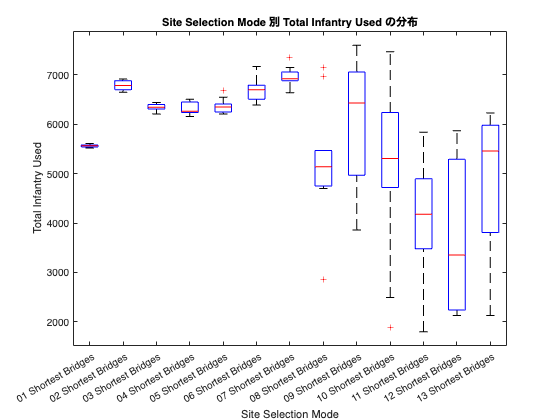


%% Graph 2: Site Selection Mode 別 Total Infantry Used の箱ひげ図
figure;
boxplot(data.total_infantry_used, data.site_selection_mode);
xlabel('Site Selection Mode');
ylabel('Total Infantry Used');
title('Site Selection Mode 別 Total Infantry Used の分布');

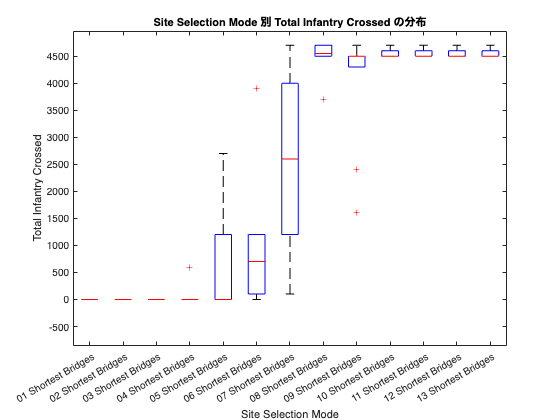


%% Graph 3: Site Selection Mode 別 Total Infantry Crossed の箱ひげ図
figure;
boxplot(data.total_infantry_crossed, data.site_selection_mode);
xlabel('Site Selection Mode');
ylabel('Total Infantry Crossed');
title('Site Selection Mode 別 Total Infantry Crossed の分布');

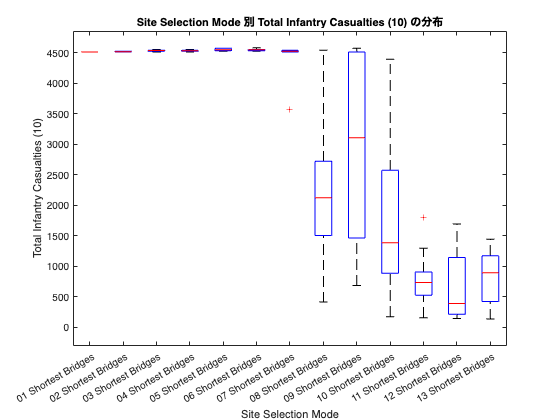


%% Graph 4: Site Selection Mode 別 Total Infantry Casualties (10) の箱ひげ図
figure;
boxplot(data.total_infantry_casualties_10, data.site_selection_mode);
xlabel('Site Selection Mode');
ylabel('Total Infantry Casualties (10)');
title('Site Selection Mode 別 Total Infantry Casualties (10) の分布');

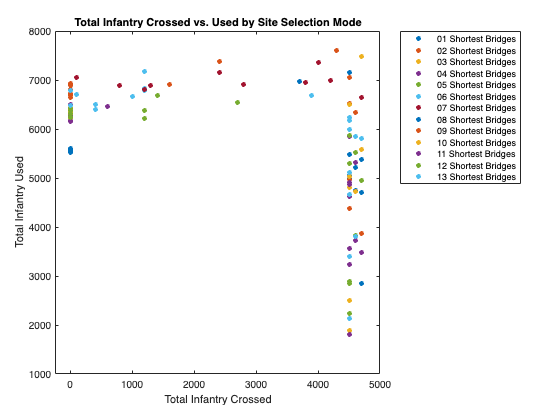


%% Graph 5: 散布図 - Total Infantry Crossed vs. Total Infantry Used（モード毎に色分け）
figure;
gscatter(data.total_infantry_crossed, data.total_infantry_used, data.site_selection_mode);
xlabel('Total Infantry Crossed');
ylabel('Total Infantry Used');
title('Total Infantry Crossed vs. Used by Site Selection Mode');
legend('Location', 'bestoutside');

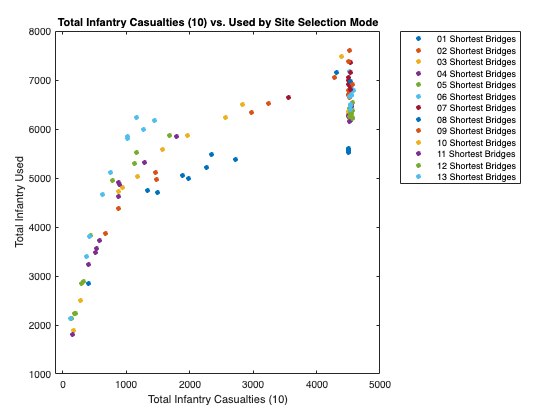


%% Graph 6: 散布図 - Total Infantry Casualties (10) vs. Total Infantry Used（モード毎に色分け）
figure;
gscatter(data.total_infantry_casualties_10, data.total_infantry_used, data.site_selection_mode);
xlabel('Total Infantry Casualties (10)');
ylabel('Total Infantry Used');
title('Total Infantry Casualties (10) vs. Used by Site Selection Mode');
legend('Location', 'bestoutside');

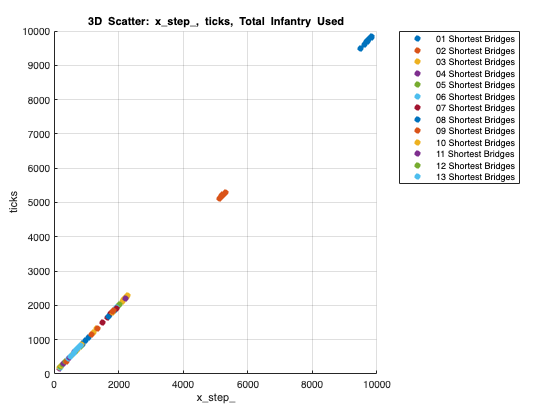


%% Graph 7: 3D 散布図 - x_step_ vs. ticks vs. Total Infantry Used（モード毎に色分け）
figure;
hold on;
% モード数に応じた色を lines カラーマップで取得
colors = lines(length(siteModes)); 
for i = 1:length(siteModes)
    idx = strcmp(data.site_selection_mode, siteModes{i});
    scatter3(data.x_step_(idx), data.ticks(idx), data.total_infantry_used(idx), 36, colors(i,:), 'filled');
end
xlabel('x\_step\_');
ylabel('ticks');
zlabel('Total Infantry Used');
title('3D Scatter: x\_step\_, ticks, Total Infantry Used');
legend(siteModes, 'Location', 'bestoutside');
grid on;
hold off;

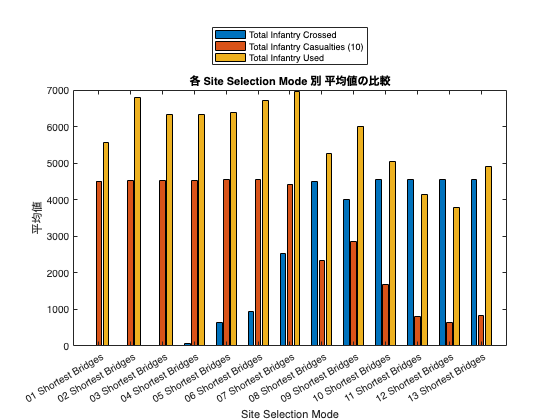


%% Graph 8: グループ化棒グラフ - 各サイト選択モードごとの平均値（Crossed, Casualties, Used）
meanCrossed = zeros(length(siteModes),1);
meanCasualties = zeros(length(siteModes),1);
meanUsed = zeros(length(siteModes),1);
for i = 1:length(siteModes)
    idx = strcmp(data.site_selection_mode, siteModes{i});
    meanCrossed(i)   = mean(data.total_infantry_crossed(idx));
    meanCasualties(i)= mean(data.total_infantry_casualties_10(idx));
    meanUsed(i)      = mean(data.total_infantry_used(idx));
end
groupMeans = [meanCrossed, meanCasualties, meanUsed];
figure;
bar(categorical(siteModes), groupMeans);
xlabel('Site Selection Mode');
ylabel('平均値');
legend('Total Infantry Crossed','Total Infantry Casualties (10)','Total Infantry Used', 'Location', 'northoutside');
title('各 Site Selection Mode 別 平均値の比較');

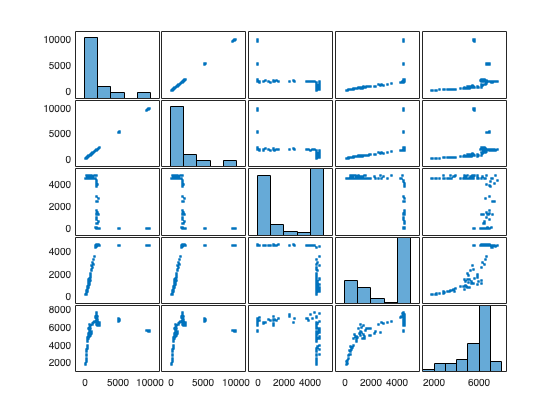


%% Graph 9: 数値変数の散布図行列（x\_step\_, ticks, Crossed, Casualties, Used）
figure;
vars = [data.x_step_, data.ticks, data.total_infantry_crossed, data.total_infantry_casualties_10, data.total_infantry_used];
varNames = {'x\_step\_', 'ticks', 'Infantry Crossed', 'Infantry Casualties', 'Infantry Used'};
plotmatrix(vars);
subtitle('数値変数の散布図行列'); % MATLAB R2018b 以降は 'sgtitle' も利用可

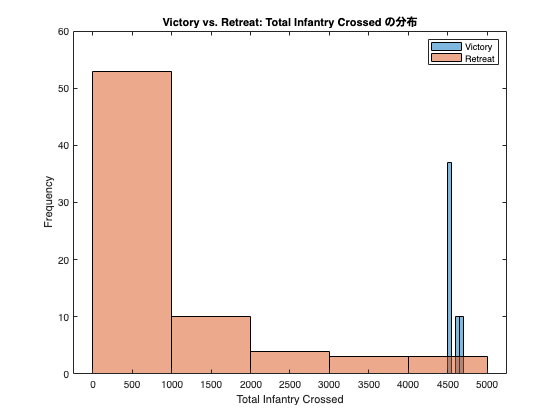


%% Graph 10: ヒストグラム - Victory と Retreat における Total Infantry Crossed の分布比較
figure;
victoryIdx = strcmp(data.battle_outcome, 'Victory');
retreatIdx = strcmp(data.battle_outcome, 'Retreat');
histogram(data.total_infantry_crossed(victoryIdx), 'FaceAlpha', 0.5, 'EdgeColor', 'k');
hold on;
histogram(data.total_infantry_crossed(retreatIdx), 'FaceAlpha', 0.5, 'EdgeColor', 'k');
hold off;
xlabel('Total Infantry Crossed');
ylabel('Frequency');
legend({'Victory', 'Retreat'});
title('Victory vs. Retreat: Total Infantry Crossed の分布');

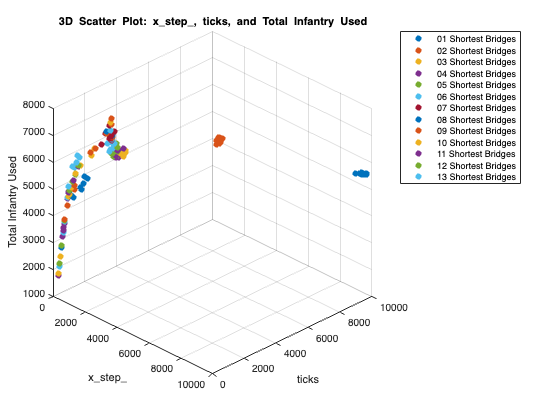


figure;
hold on;
% site_selection_mode ごとに異なる色を割り当てる
colors = lines(length(siteModes));  % lines カラーマップを利用
for i = 1:length(siteModes)
    % 現在の mode に対応する行を抽出
    idx = strcmp(data.site_selection_mode, siteModes{i});
    % 3次元散布図: x_step_, ticks, total_infantry_used
    scatter3(data.x_step_(idx), data.ticks(idx), data.total_infantry_used(idx), 36, colors(i,:), 'filled');
end
xlabel('x\_step\_');
ylabel('ticks');
zlabel('Total Infantry Used');
title('3D Scatter Plot: x\_step\_, ticks, and Total Infantry Used');
legend(siteModes, 'Location', 'bestoutside');
grid on;
% 視点の設定（角度は必要に応じて調整可能）
view(45, 30);
hold off;